% Astrodynamics master code

% functions
orbitalPeriod = @(a,mu) 2*a^(3/2)*pi*mu^(-1/2); %finds orbital period from mu and the semimajor axis a

orbitalVelocity = @(r,a,mu) sqrt((2*mu/r)-(mu/a)); % finds orbital period from the position r the semi major axis a and mu

orbitalEnergy = @(a,mu) mu/(a*2); % finds orbital energy from mu and the semimajor axis a]

% magnitude of a 3 element vector
mag = @(vector) sqrt(vector(1)^2 + vector(2)^2 + vector(3)^2);

% constants for earth
duE = 6378.136; % conversion from du earth to km
tuE = 806.8118744; % converson from tu earth to seconds
muE = 3.986004418*10^5; % mu for earth

% constants for the sun
duS = 1.4959965*10^8; % conversion from du sun to km
au = duS; % a sun du is sometimes called a au
tuS = 5.0226757*10^6; % converson from tu sun to seconds
muS = 1.3271544*10^11; % mu for sun


% r and v vectors that define a orbit and position
r = [0.1 0.2 0.3];
v = [0 -1 1];
    
elements = rv2elements(r,v,1)

elements = struct with fields:
           a: 0.2989
           e: 0.3111
           i: 101.0958
    bigOmega: 78.6901
       omega: 261.3029
          nu: 153.4884
           u: 54.7913


[r,v] = elements2rv(elements,1)

r =     0.1000
    0.2000
    0.3000


v =    -0.0000
   -1.0000
    1.0000


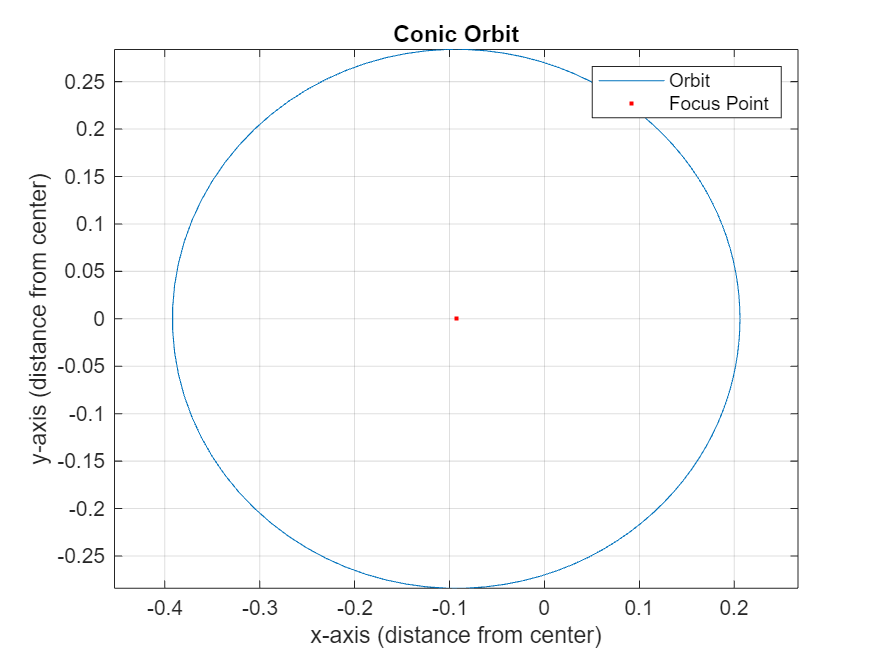

displayOrbit(elements,1)




dTilda = [sind(L)*cosd(theta) sind(L)*sin(theta) -cosd(L);
          -sind(theta) cosd(theta) 0;
          cosd(L)*cosd(theta) cosd(L)*sind(theta) sind(L)]

dTilda =    -0.0653   -0.0552   -0.8660
   -0.9914   -0.1305         0
   -0.1130    0.8586    0.5000


rijk = dTilda^(-1)*rSEZ'

rijk = 1.0e+03 *

   -1.0910
    8.2873
   -0.4460
